Exercícios:

1) Determine a raiz real de $x^{3,5}=80$, com o método das secantes até erro relativo seja 0,1% usando aproximações iniciais de $x_{0}=3$ e  $x_{1}=4$.

format long
%Chute inicial
x0 = 3;
x1 = 4;
fx0 = fun(x0);
tol = 10^-3;
k = 0;
er = abs(x1-x0)/abs(x1);
while(er >= tol)
    x = (x0*fun(x1)-x1*fun(x0))/(fun(x1)-fun(x0)); %atualizando o zero da função usando o metodo das secantes
    x0 = x1;
    x1 = x;
    er = abs(x1-x0)/abs(x1);%calculando erro relativo
    % fx0 = fun(x0);
    k = k+1;
    xk(k,:) = x0;
    fk(k,:) = fun(x0);
    erk(k,:) = er;
end
[xk,fk, erk]

ans =    4.000000000000000  48.000000000000000   0.173323672167212
   3.409118979600672  -6.844403657695608   0.021172270881867
   3.482859014090345  -1.154732472324994   0.004278578480118
   3.497824731714683   0.037433597158881   0.000134363917419


2) Use o método de Newton-Raphson para encontrar a raiz de $f(x)=e^{-0,5x}(4-x)-2$.

Use aproximações iniciais de $x^{0}=2$, $x^{0}=3$, $x^{0}=4$. Explique os resultados.

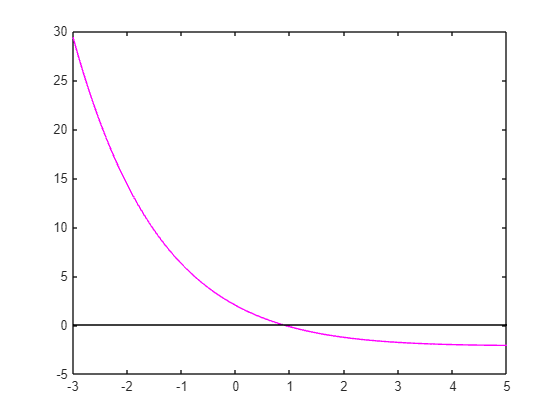

x= -3:0.01:5;
y = fun2(x);
plot(x,y,'magenta')
y1 = 0*x;
hold on 
plot(x,y1, 'black')
hold off

format long
%Chute inicial
x0 = 2;
fx0 = fun2(x0);
tol = 10^-7;
k = 0;
er = 2;
while(er > tol)
    x = x0 - (fun2(x0)/dfun2(x0)); %atualizando o zero da função usando o metodo de newton-raphson
    er = abs(x-x0)/abs(x);%calculando erro relativo
    x0 = x;
    fx0 = fun2(x0);
    k = k+1;
    xk(k,:) = x0;
    fk(k,:) = fx0;
    erk(k,:) = er;
end
[xk,fk, erk]

ans =    0.281718171540955   1.229743110593619   6.099293556607686
   0.776886845045375   0.185630375418450   0.637375541447737
   0.881707878928567   0.006579468330556   0.118884084386961
   0.885703241166645   0.000009132029956   0.004510949099401
   0.885708801994023   0.000000000017660   0.000006278392363
   0.885708802004777                   0   0.000000000012142


format long
%Chute inicial
x3 = 3;
fx03 = fun2(x3);
tol3 = 10^-7;
k3 = 0;
er3 = 2;
while(er3 > tol3)
    xn = x3 - (fun2(x3)/dfun2(x3)); %atualizando o zero da função usando o metodo de newton-raphson
    er3 = abs(xn-x3)/abs(xn);%calculando erro relativo
    x3 = xn;
    fx03 = fun2(x3);
    k3 = k3+1;
    xk3(k,:) = x3;
    fk3(k,:) = fx03;
    erk3(k,:) = er3;
end
[xk3,fk3, erk3]

ans =                    0                   0                   0
                   0                   0                   0
                   0                   0                   0
                   0                   0                   0
                   0                   0                   0
   0.885708802004777  -0.000000000000000   0.000000000359220


3) (a) Aplique o método de Newton-Raphson à função $f(x)=\tanh{(x^{2}-9)}$ para calcular sua raiz real conhecida $x^{*}=3$. Use uma aproximação inicial de $x^{0}=3,2$ e faça um mínimo de 4 iterações;

(b)O método convergiu para sua raiz real? Esboce o gráfico, com os resultados para cada iteração.

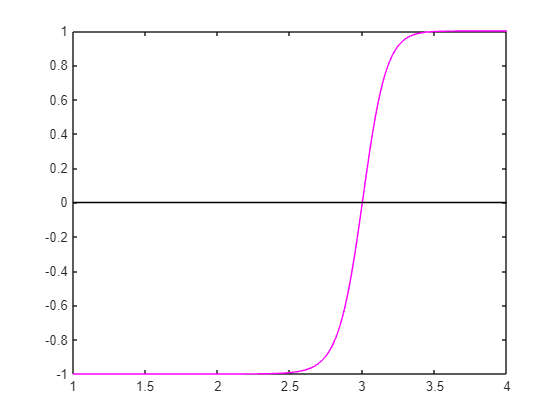

x= 1:0.01:4;
y = fun3(x);
plot(x,y,'magenta')
y1 = 0*x;
hold on 
plot(x,y1, 'black')
hold off        

4) Você está projetando um tanque esférico para armazenar água para uma pequena vila em um país em desenvolvimento. O volume de líquido que ele pode armazenar pode ser calculado por 


$$V = \pi h^{2} \frac{(3R-h)}{3}$$


onde $V$ é o volume $m^{3}$, $h$ é a profundidade no tanque $m$ e $R$ é o raio do tanque $m$.

Se $R=3 \ m$, até qual profundidade $h$ o tanque deve ser enchido para que armazene $30 \ m^{3}$? Use 3 iterações do método de Newton-Raphson para determinar sua resposta. Determine o erro relativo aproximado a cada iteração

% Método de Newton-Raphson
h = 2; % Aproximação inicial
tol = 1e-6;
max_iter = 3;

for k = 1:max_iter
    h_prev = h;
    fh = fun4(h);
    dfh = dfun4(h);
    h = h - fh / dfh;
    er = abs(h - h_prev) / abs(h);
    fprintf('%2d | %9.6f |%12.6f\n', k, h, er*100);
end

 1 |  2.026995|    1.331794
 2 |  2.026906|    0.004424
 3 |  2.026906|    0.000000


fprintf('\nProfundidade h ≈ %.6f metros\n', h);


Profundidade h ≈ 2.026906 metros


**Definindo as funções que serão utilizadas:**

syms x
function f1 = fun(x)
    f1 = x.^3.5 - 80;
end
function f2 = fun2(x)
    f2 = exp(-0.5*x).*(4-x)-2;
end
function g2 = dfun2(x)
    g2 = (exp(-x/2).*(x-4))/2 - exp(-x/2);
end
function f3 = fun3(x)
    f3 = tanh(x.^2-9);
end

function y = fun4(h)
    y = pi * h.^2 .* (9 - h) - 90;
end
function y = dfun4(h)
    y = 3 * pi * h .* (6 - h);
end